# **Simulation parameters for a 4 wheel, 3-dof car model:**

This script serves as a "Data Dictionary" for defining parameters used by our car dynamics model.

The expectation is that you run this script to define parameters into the base MATLAB workspace.

In your Simulaink models you then reference these defined parameters.

` Bradley Horton : 27-Nov-2017, bradley.horton@mathworks.com.au`

## Some utilities:

Inertia of a cylinder about it's longitudinal axies:

- *REF:  *[*https://en.wikipedia.org/wiki/List_of_moments_of_inertia*](https://en.wikipedia.org/wiki/List_of_moments_of_inertia) 

Izz_func_han = @(m,r) ((1/2) * m * r^2);

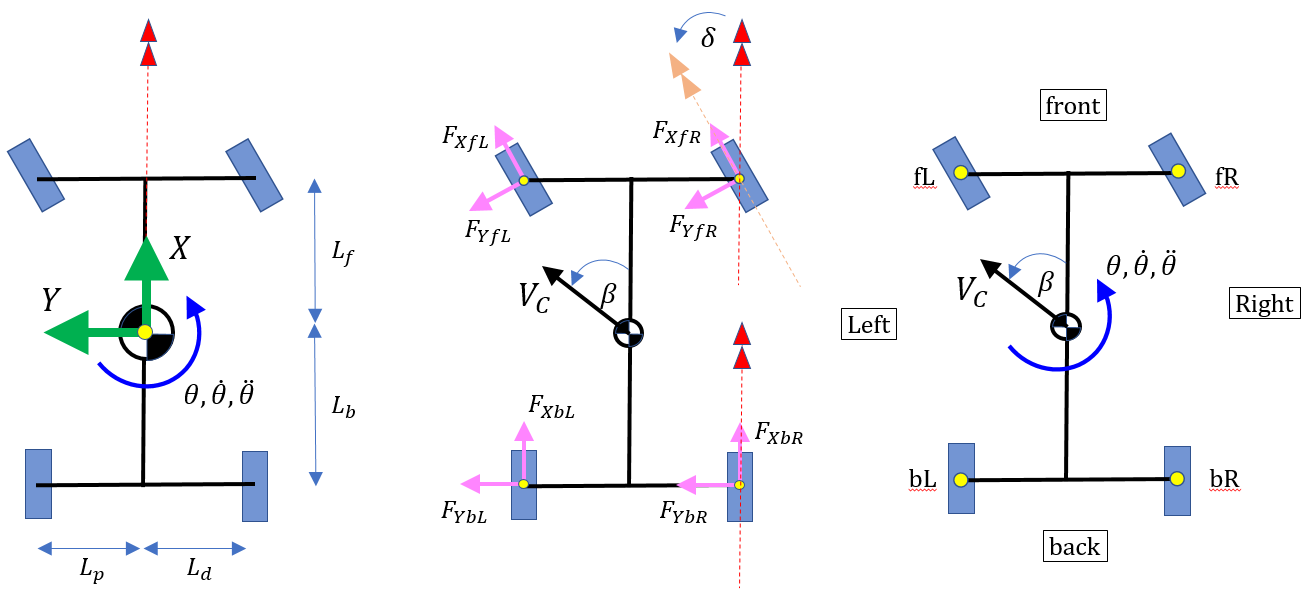

## Steering:  $\delta$

% steering angle limit
veh.steering_delta_deg_max =   45;  % degrees
veh.steering_delta_deg_min =  -45;  % degrees

## Vehicle GEOMETRY and INERTIA:

% Vehicle geometry
veh.Lf  = 0.2;              % m 
veh.Lb  = 0.2;              % m 
veh.Lp  = 0.1;              % m
veh.Ld  = 0.1;              % m

% Vehicle MASS properties
veh.mass    = 1.5;   % kg
veh.Inertia = 0.04;  % kg.m^2

## Vehicle STATES:

veh.states.init_vel_B_Cx       = 0;     % m/sec
veh.states.init_vel_B_Cy       = 0;     % m/sec
veh.states.init_theta_pos_deg  = 0;     % deg
veh.states.init_theta_vel_deg  = 0;     % deg/sec
veh.states.init_pos_G_Cxy      = [1.5;0]; % m
% derived states
veh.states.init_theta_pos_rad  = veh.states.init_theta_pos_deg * pi/180;    % rad
veh.states.init_theta_vel_rad  = veh.states.init_theta_vel_deg * pi/180;    % rad/sec
veh.states.init_pose           = [veh.states.init_pos_G_Cxy(:);
                                  veh.states.init_theta_pos_deg*(pi/180)];

## Wheels:

veh.wheel.r      = 4/100;       % m  (radius of cylinder)
veh.wheel.h      = 3/100;       % m  (height of cylinder)
veh.wheel.mass   = 50/1000;     % kg
veh.wheel.I      = Izz_func_han(veh.wheel.mass, veh.wheel.r);  % kg.m^2
veh.wheel.bR     = 4.1142324090730581E-7;   % N.m.s
veh.wheel.bL     = 4.1142324090730581E-7;   % N.m.s

## Shafts and axles:

                                           %      m ,    r
veh.shaft.I_common_rear_axle = Izz_func_han( 120/1000,    3/1000);   % kg.m^2
veh.shaft.m_common_rear_axle =  120/1000;                            % kg
veh.shaft.B                  = 1e-5;       % (N.m.sec/rad) Viscous friction co-efficient

## Tyres:

- REF:   [http://racingcardynamics.com/racing-tires-lateral-force/](http://racingcardynamics.com/racing-tires-lateral-force/)

tmp_C = 2;   % N/rad
veh.tyres_S.Rolling_resistance_of_tyre_N = 0.024;  % N

% LATERAL Tyre Force = Slip_Angle * CLat
veh.tyres_S.CLat.fR = tmp_C;
veh.tyres_S.CLat.fL = tmp_C;
veh.tyres_S.CLat.bR = tmp_C;
veh.tyres_S.CLat.bL = tmp_C;

## MOTOR:

                     %        m ,    r
tmp_J     = Izz_func_han(30/1000, 0.003);

mot_bR.K  = 0.1; %0.010808;   % (N.m/A)       Torque constant
mot_bR.Kb = mot_bR.K;   % (V.sec/rad)   Back EMF constant
mot_bR.B  = 1e-5;       % (N.m.sec/rad) Viscous friction co-efficient
mot_bR.J  = tmp_J;      % (kg.m^2)      Rotor ONLY Inertia
mot_bR.R  = 1.07;       % (Ohms)        Armature resistamce
mot_bR.L  = 6.0793E-05; % (Henry)       Armature Inductance
mot_bR.G  = 1;  % gear ratio (==win/wout ==Tout/Tin)
mot_bL    = mot_bR;

% COMMON MOTOR params
mot_COM.Vmax_sat =  7.4;  % volts
mot_COM.Vmin_sat = -7.4;  % volts

## Create the Simulink BUS objects:

bh_create_car_Simulink_BUS_objects()